Digital Signal Processing Lab (EE-384L)

# Assignment No. 4:   **Z-Transform**

### Reg. No. :   **2016-EE-189**

## Task 1

**Statement:**

Let


$$H\left(z\right)\;=\;\frac{1-2\cos \left(\omega_0 \right)z^{-1} +z^{-2} }{1+0\ldotp 5z^{-1} }$$


where $\omega_0 =2000\pi /F_s$, and sampling rate $F_s =11025\;\textrm{samples}/\textrm{second}$.

**Question (1):**

Find inverse Z-transform of $H\left(z\right)$ on paper.

Find all poles and zeros and draw them in z-plane.

**Answer (1):**

The work done on paper, i.e. inverse Z-transform and pole-zero plot of $H\left(z\right)$, has been attached starting at the next page.

*The work done on paper starts from the next page.*

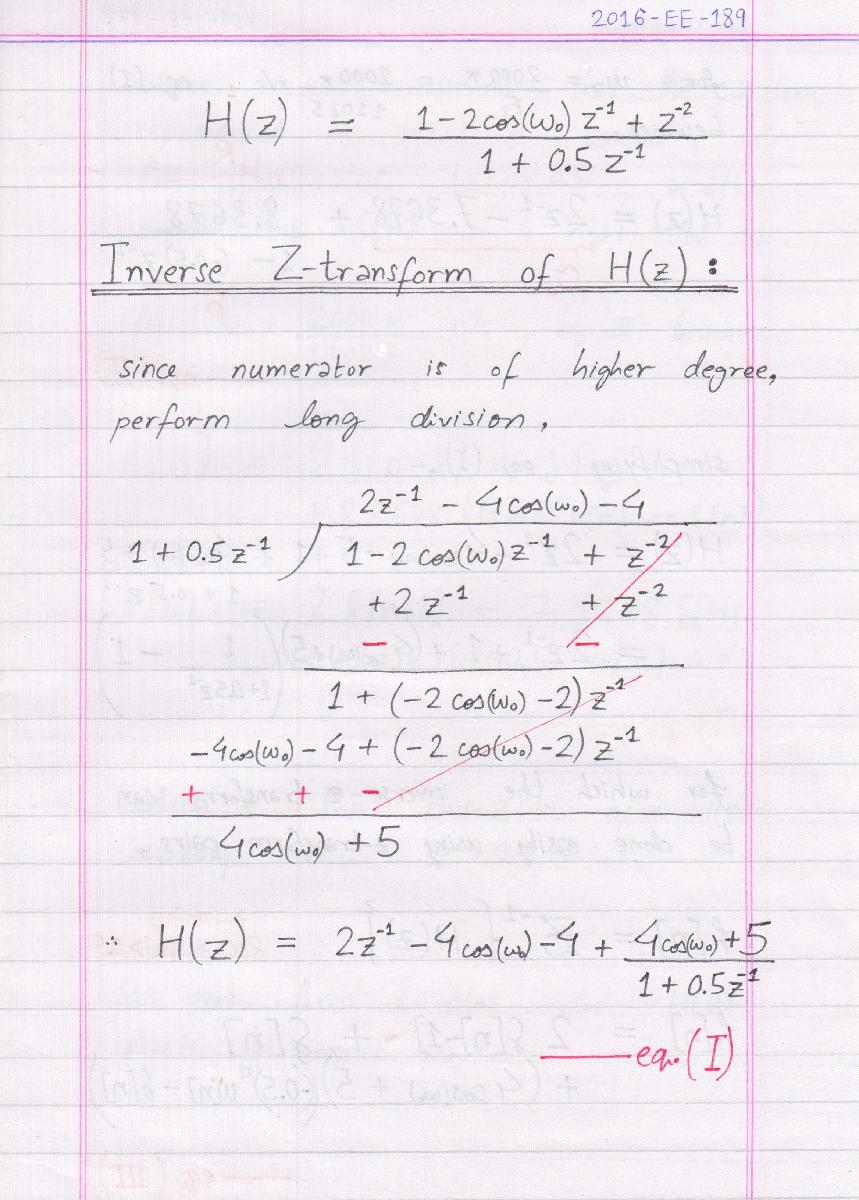

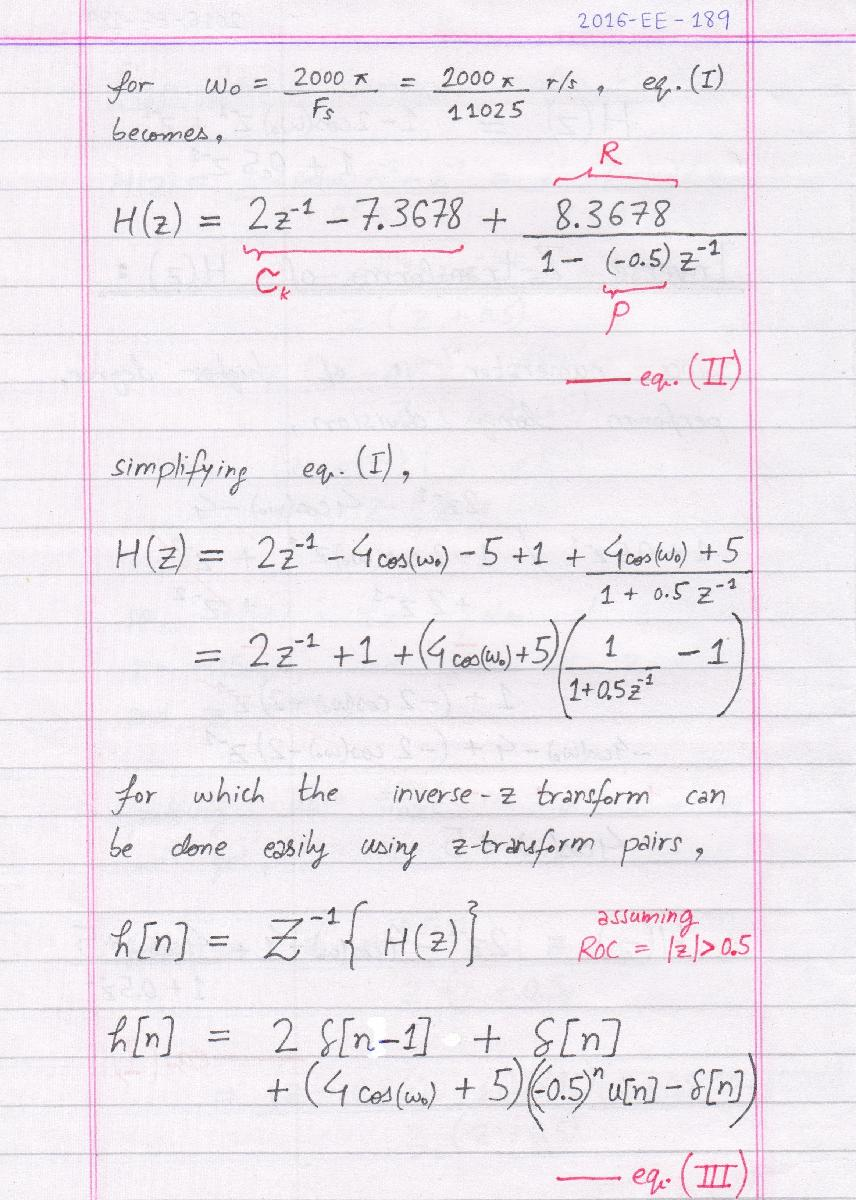

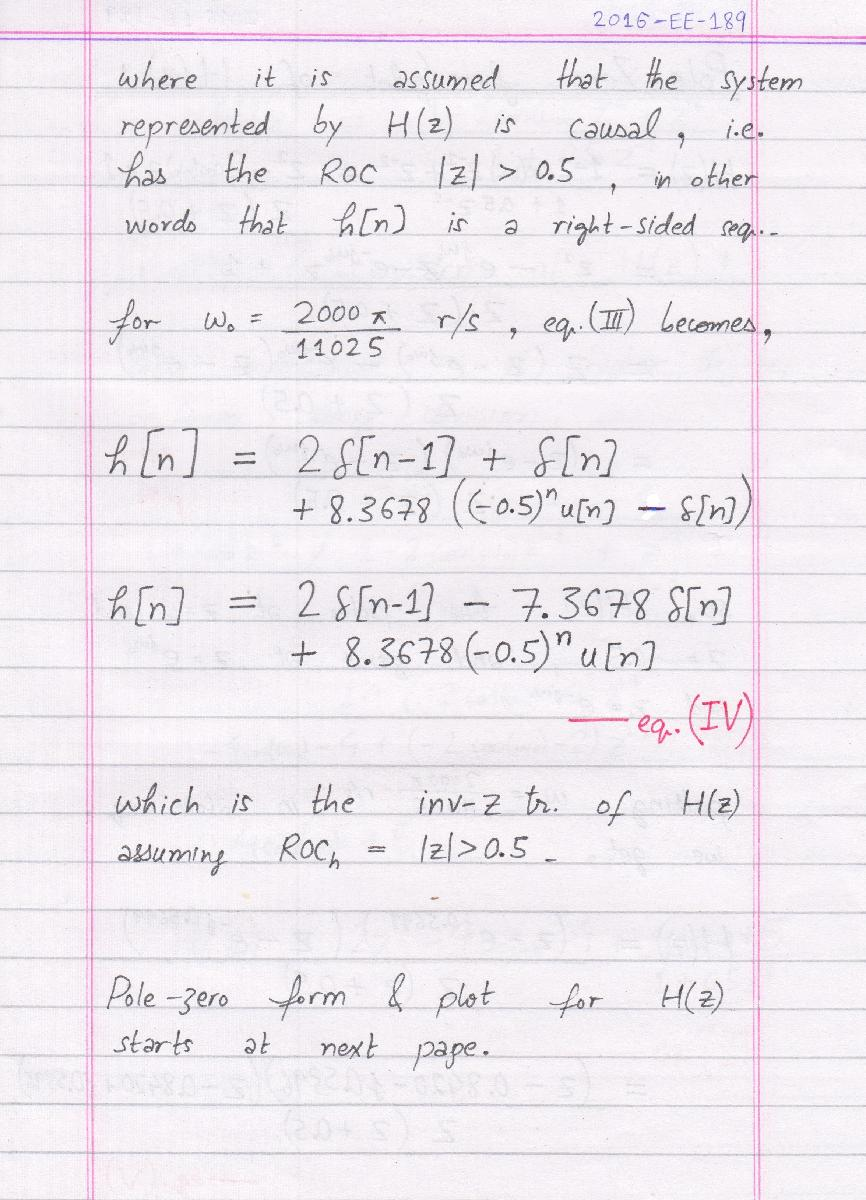

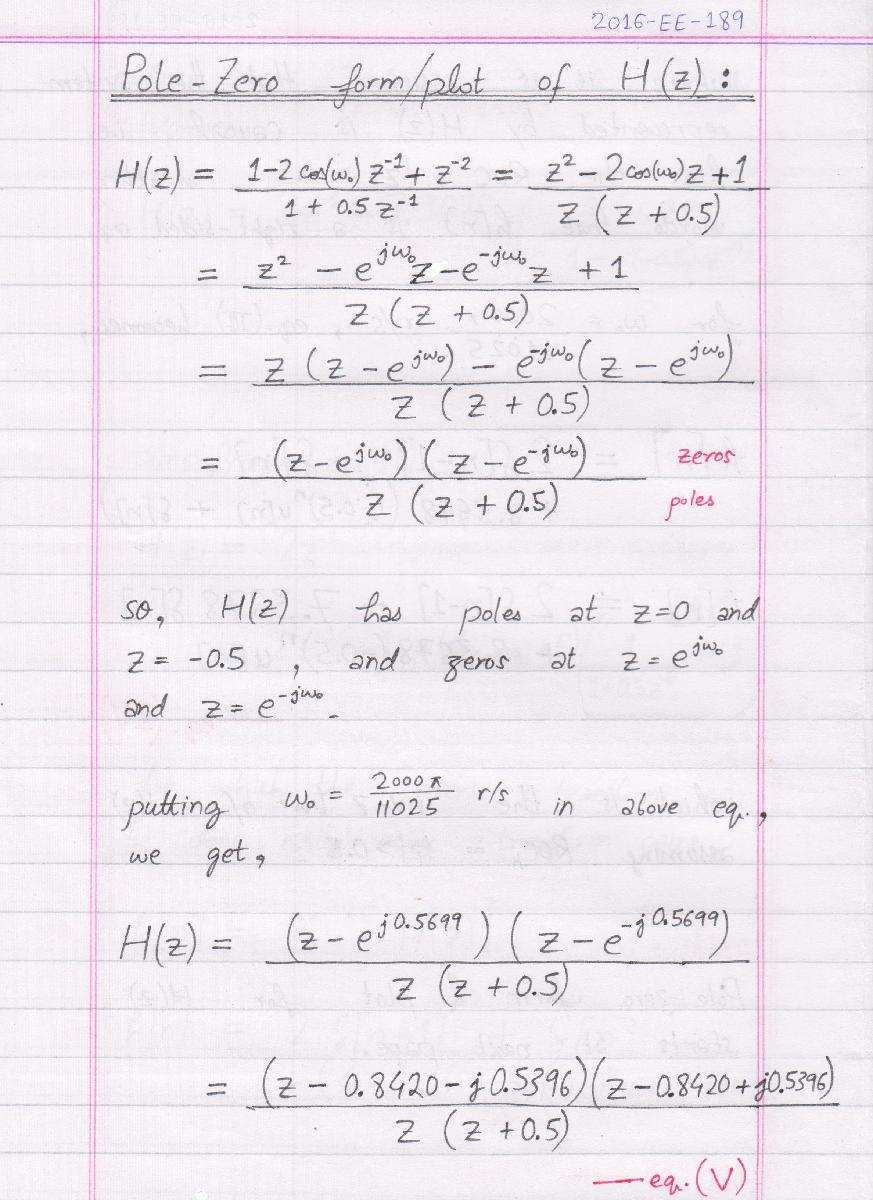

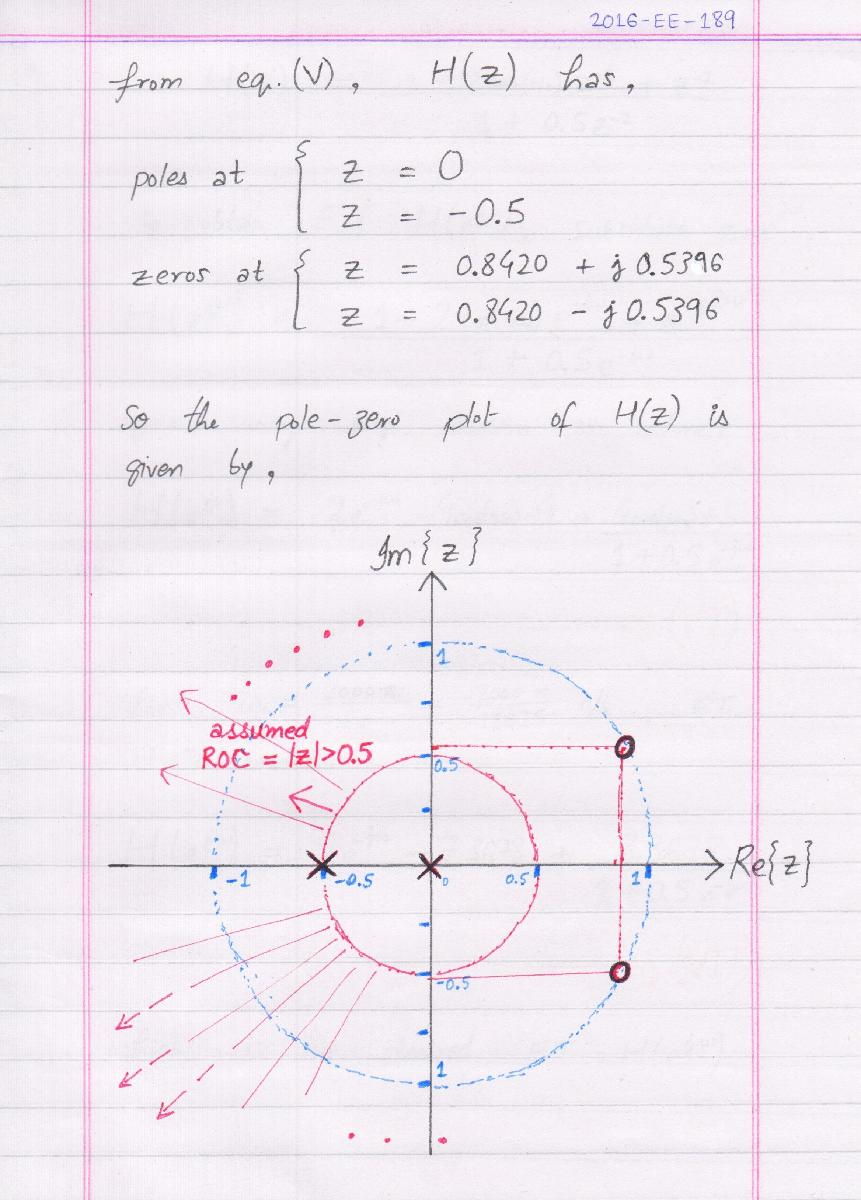

**Question (2):**

Find inverse Z-transform of $H\left(z\right)$ using MATLAB. Plot all poles and zeros in z-plane using MATLAB.

**Answer (2):**

The code, alongwith the results, to compute inverse Z-tranform of $H\left(z\right)$ and plot its pole-zero map starts below.

% >>> task <<< compute inverse Z-transform of H(z)

% define sampling frequency Fs and corresponding w0
Fs = 11025;
w0 = 2000*pi/Fs;

% [method 1] using iztrans()

% define H(z) symbolically
syms z;
syms w_0;
Hz = vpa((1-2*cos(w_0)*(z^-1)+(z^-2))/(1+0.5*(z^-1)))

$$Hz = \frac{\frac{1}{z^{2}}-\frac{2.0\,\cos\left(w_{0}\right)}{z}+1.0}{\frac{0.5}{z}+1.0}$$


% compute inverse Z-transform of H(z) using iztrans()
% <syntax> f = iztrans(F, transVar)
h = vpa(iztrans(Hz))

$$h = \left(4.0\,\cos\left(w_{0}\right)+5.0\right)\,\left(1.0\,{\left(-0.5\right)}^{n}-1.0\,\delta_{n,0}\right)+2.0\,\delta_{n-1.0,0}+1.0\,\delta_{n,0}$$

*Which matches the inverse Z-transform in eq. (III) derived on paper.*


% substitute w0 value to get numerical sequence h[n]
h = vpa(subs(h, {w_0}, {w0}), 5)

$$h = 8.3678\,{\left(-0.5\right)}^{n}+2.0\,\delta_{n-1.0,0}-7.3678\,\delta_{n,0}$$

*Which matches the inverse Z-transform in eq. (IV) derived on paper.*


% save h[n] expression as function-handle for later use
func_h = matlabFunction(h)

func_h = function_handle with value:
    @(n)(-5.0e-1).^n.*8.367812335691269+(n-1.0==0.0).*2.0-(n==0.0).*7.367812335691269



% [method 2] using residuez() (partial fraction decomposition)

% b's and a's in poly. frac H(z)=B(z)/A(z) are,
b = [1 -2*cos(w0) 1];
a = [1 0.5];

% compute partial fraction form of H(z) using residuez()
% <syntax> [r, p, k] = residuez(b, a)
[R, p, C] = residuez(b, a)

R = 8.3678

p = -0.5000

C =    -7.3678    2.0000



% display partial fraction sum symbolically
Hz = sum(R./(1-p*z^-1));
if ~isempty(C)
    Hz = Hz + sum(C.*z.^-(0:length(C)-1));
end
Hz = vpa(Hz, 5)

$$Hz = \frac{8.3678}{\frac{0.5}{z}+1.0}+\frac{2.0}{z}-7.3678$$

*Which matches the partial fraction decomposition in eq. (II) derived on paper.*

This result can be used to easily compute inverse Z-transform of $H\left(z\right)$, using Z-transform properties and pairs, as follows:


$$H\left(z\right)\;=\;\frac{8\ldotp 3678}{1+0\ldotp 5z^{-1} }+2z^{-1} -7\ldotp 3678$$


Assuming ${\textrm{ROC}}_h$ is $|z|>0\ldotp 5$, the inverse Z-transform is,


$$\begin{array}{l}
h\left\lbrack n\right\rbrack \;=\;Z^{-1} \left\lbrace \;H\left(z\right)\;\right\rbrace \\
\;\;\;\;\;\;\;\;\;\;=\;8\ldotp 3678{\;\left(-0\ldotp 5\right)}^n \;u\left\lbrack n\right\rbrack +2\;\delta \left\lbrack n-1\right\rbrack -7\ldotp 3678\;\delta \left\lbrack n\right\rbrack \\
\;\;\;\;\;\;\;\;\;\;=\;2\;\delta \left\lbrack n-1\right\rbrack -7\ldotp 3678\;\delta \left\lbrack n\right\rbrack +8\ldotp 3678{\;\left(-0\ldotp 5\right)}^n \;u\left\lbrack n\right\rbrack 
\end{array}$$


*Which matches the inverse Z-transform in eq. (IV) derived on paper.*

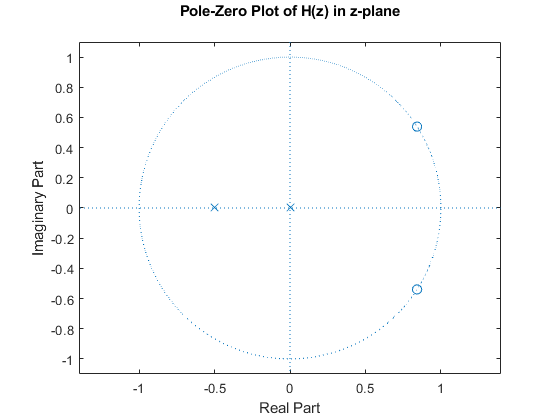


% >>> task <<< plot all poles and zeros of H(z) in z-plane

% coefficients (b's and a's) in poly. frac H(z)=B(z)/A(z) are,
b = [1 -2*cos(w0) 1];
a = [1 0.5];

% plot pole-zero map of H(z) using zplane() with b's and a's from H(z)=B(z)/A(z)
% <syntax> zplane(b, a)
zplane(b, a);
title({'Pole-Zero Plot of H(z) in z-plane';''});

**Question (3):**

Substitute $z=e^{j\omega }$ in $H\left(z\right)$ and calculate its Fourier Transform $H\left(e^{j\omega } \right)$ on paper. Plot the response using MATLAB.

What kind of a system do you think it is? (Question 4)

**Answer (3):**

The work done on paper, i.e. deriving $H\left(e^{j\omega } \right)$, has been attached starting at the next page.

*The work done on paper starts from the next page.*

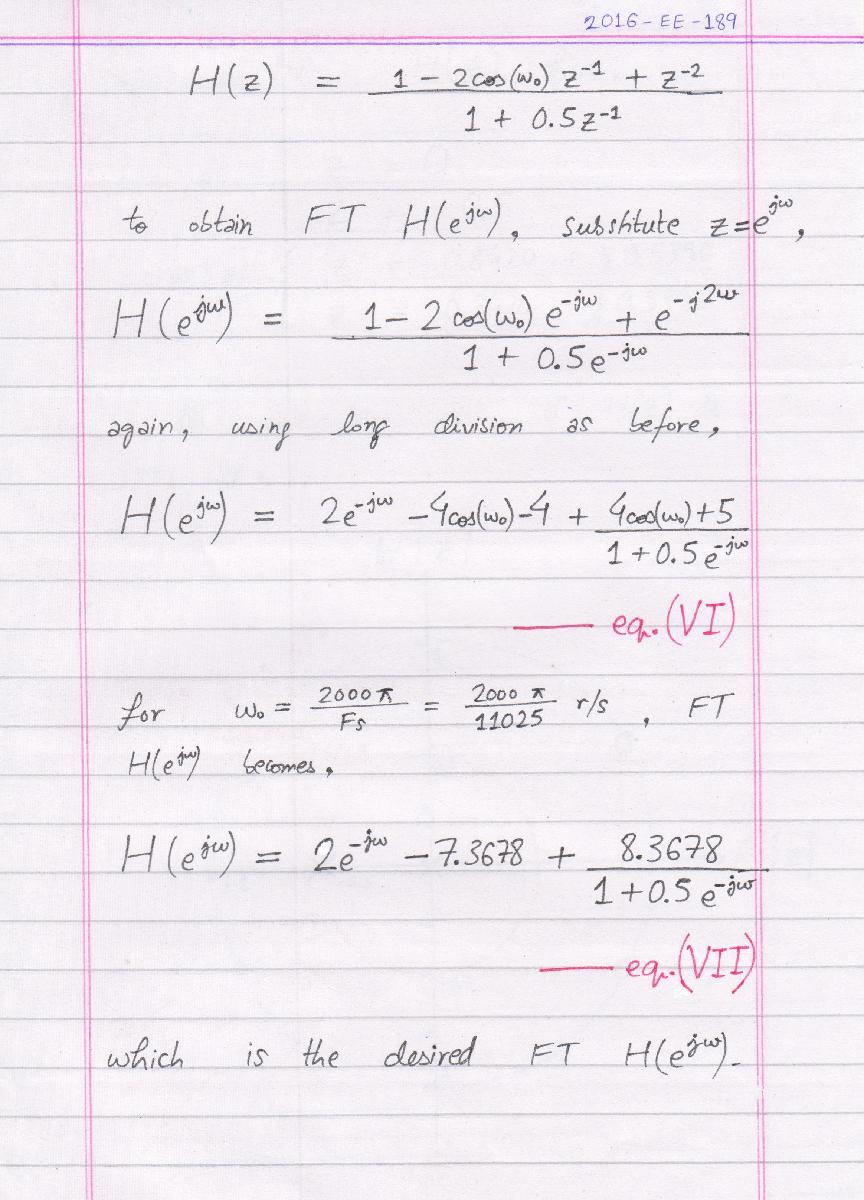

The expression for $H\left(e^{j\omega } \right)$, given by eq. (VI) derived on paper, has been used in the code below to plot the frequency response $H\left(e^{j\omega } \right)$ of the system.

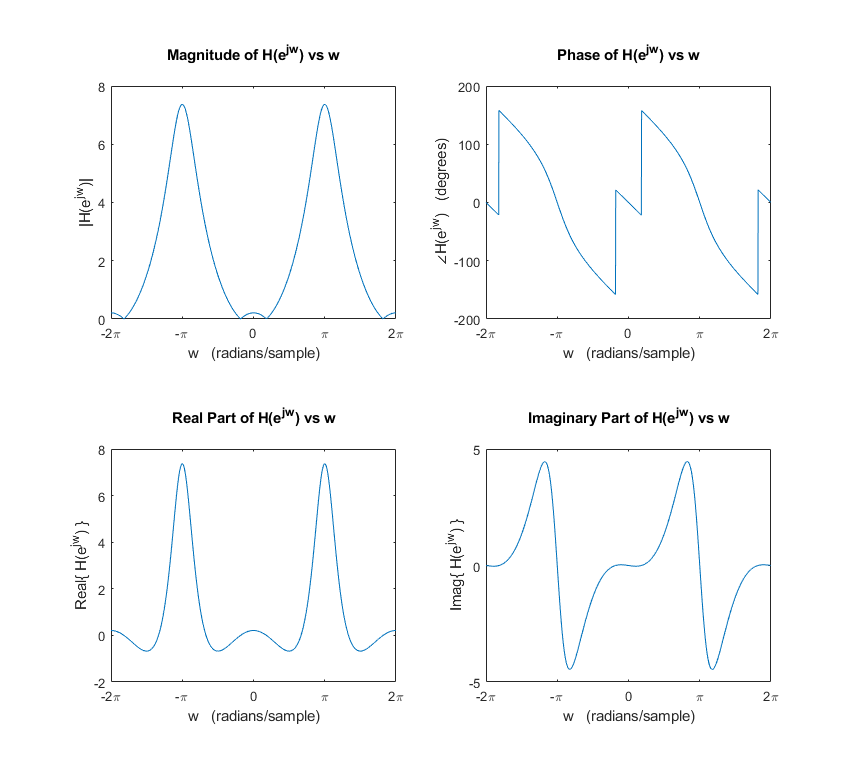

% initialize frequency vector for computing freq. resp. H(w)
w = -2*pi:0.01:2*pi;

% compute freq. resp. H(w) using derived equation eq. (VI) on paper
Hw = 2*exp(-1i*w) - (4*cos(w0)+4) + (4*cos(w0)+5)./(1+0.5*exp(-1i*w));

% obtain magnitude and phase of freq. resp. H(w)
Hw_mag = abs(Hw);                           % get the magnitude of H(w)
Hw_ang = angle(Hw)*180/pi;                  % get the phase (angle) of H(w) in degrees
 
% obtain real and imaginary parts of freq. resp. H(w)
Hw_real = real(Hw);                         % get the real part of H(w)
Hw_imag = imag(Hw);                         % get the imaginary part of H(w)
 
% plot magnitude and phase of freq. resp. H(w), 
% and also its real and imaginary parts
fig = figure; set(fig,'Units','normalized','Position',[0 0 1 1.6]); 

% plot magnitude of H(w) vs w
subplot(2, 2, 1);
plot(w, Hw_mag);
xlabel('w   (radians/sample)');
ylabel('|H(e^{jw})|');
title({'Magnitude of H(e^{jw}) vs w';''});
setDTFTradialAxis()

% plot phase of H(w) vs w
subplot(2, 2, 2);
plot(w, Hw_ang);
xlabel('w   (radians/sample)');
ylabel('∠H(e^{jw})   (degrees)');
title({'Phase of H(e^{jw}) vs w';''});
setDTFTradialAxis()

% plot real part of H(w) vs w
subplot(2, 2, 3);
plot(w, Hw_real);
xlabel('w   (radians/sample)');
ylabel('Real\{ H(e^{jw}) \}');
title({'';'Real Part of H(e^{jw}) vs w';''});
setDTFTradialAxis()

% plot imaginary part of H(w) vs w
subplot(2, 2, 4);
plot(w, Hw_imag);
xlabel('w   (radians/sample)');
ylabel('Imag\{ H(e^{jw}) \}');
title({'';'Imaginary Part of H(e^{jw}) vs w';''});
setDTFTradialAxis()

**Question (4):**

Based on the shape of it’s response, what kind of a system do you think it is?

**Answer (4):**

Consider the DTFT plot in the range $\omega =\left\lbrack -\pi ,\;\pi \right\rbrack$ (i.e. one period of the response).

From the plot of real part of $H\left(e^{j\omega } \right)$ in above figure, the system appears to be a sinc filter, with the sinc-center  shifted to $-\pi$ and $\pi$.

Based on the plot of magnitude part of $H\left(e^{j\omega } \right)$, the system can be considered to be allowing most frequencies through but reducing the strength of very lower frequencies (near $0$), meanwhile giving relatively more magnitude to higher frequencies (near $\pm \pi$).

Note that at $\omega =\left\lbrace 0\ldotp 1814\pi ,\;-0\ldotp 1814\pi \right\rbrace$, there is a sharp dip (a cutoff for a single point), where magnitude drops to nearly zero. Hence that frequency will effectively be removed from an input given to this system.

Given the sampling frequency $F_s =11025\;\textrm{samples}/\textrm{second}$, this radial frequency $0\ldotp 1814\pi$ corresponds to,


$$F\;=\;\frac{\Omega }{2\pi }\;=\;\frac{\omega \times F_s }{2\pi }\;=\;\frac{0\ldotp 1814\pi \times 11025}{2\pi }\;\textrm{Hz}\;\approx \;1\;\textrm{kHz}$$


Hence, besides affecting the magnitudes of various frequencies, this filter will essentially remove the frequency component at $\omega =\pm 0\ldotp 1814\pi$, corresponding to $F\approx 1\;\textrm{kHz}$ for an input sampled at $F_s =11025\;\textrm{samples}/\textrm{second}$.

## Task 2

**Statement:**

Write a function like you have written in previous lab to compute output of the system $H\left(z\right)$, assuming the system is initially at rest. Plot the impulse response of the system.

**Methodology:**

A function "$\textrm{get}\_\textrm{system}\_\textrm{out}\left(\right)$" that implements a CCDE (computes its output $y\left\lbrack n\right\rbrack$ for $0\le n<\textrm{len}\left(x\right)$, where $x\left\lbrack n\right\rbrack$ is the input) given the system's CCDE coefficients ($b$'s and $a$'s) has already been implemented in assignment 3.

To compute system impulse response using $H\left(z\right)$, the CCDE coeffiecients must first be extracted, and then they can be used to invoke the regular "$\textrm{get}\_\textrm{system}\_\textrm{out}\left(\right)$" function with input $x\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack$. This process has been implemented in the respective 2 steps, using the below functions "$\textrm{get}\_\textrm{zsys}\_\textrm{coeffs}\left(\right)$" and "$\textrm{get}\_\textrm{sys}\_\textrm{imp}\_\textrm{resp}\left(\right)$".

**Code (*****get_zsys_coeffs*****.*****m*****):**

Firstly, the following function "$\textrm{get}\_\textrm{zsys}\_\textrm{coeffs}\left(\right)$" (on next page) accepts a $H\left(z\right)$ expression in the form, 


$$H\left(z\right)\;=\;\frac{Y\left(z\right)}{X\left(z\right)}\;=\;\frac{\sum_{m\;=\;0}^M b_m \;z^{-m} }{1+\sum_{k\;=\;1}^N a_k \;z^{-k} }\;=\;\frac{B\left(z\right)}{A\left(z\right)}$$


and extracts the system CCDE coefficients ($b$'s and $a$'s).

% <function>
% computes system CCDE coefficients (b's and a's) from the system
% Z-domain frequency response expression H(z).
%
% <syntax>
% [b, a] = get_zsys_coeffs(Hz)
%
% <I/O>
% b = M+1 coefficients { b0, b1, ..., bM } for { x[0], x[-1], ..., x[-M] }
% a = N+1 coefficients { a0, a1, ..., aN } for { y[0], y[-1], ..., y[-N] }
% Hz = system H(z) expression (type 'sym') of form B(z)/A(z) 
%    = (b0 + b1.z^-1 + ..... + bM.z^-M)/(a0 + a1.z^-1 + ..... + aN.z^-N)

function [b, a] = get_zsys_coeffs(Hz)
    
    % Hz must not contain any other symvars besides 'z'
    syms z;
    if ~isequal(symvar(Hz), z)
        error("Only H(z) expressions with single default symvar 'z' are acceptable");
    end
    
    % NOTE:
    % Hz must be of form B(z)/A(z) 
    %    = (b0 + b1.z^-1 + ..... + bM.z^-M)/(a0 + a1.z^-1 + ..... + aN.z^-N)
    % for the following method to work
    
    syms repl;                      % replacement symvar
    
    % replace z^-1 with replacement var 'repl' 
    % to keep its degree consistent in the next step
    H2 = subs(Hz, z^-1, repl);
    
    % separate numerator and denominator polynomials
    [N, D] = numden(H2);
    
    % extract coefficients b's and a's
    b = coeffs(N);
    a = coeffs(D);
    
    % normalize the coefficients
    a = a./a(1);
    b = b./b(1);
    
end

Next, for the impulse response, input $x\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack$ is given to the system, where $\delta \left\lbrack n\right\rbrack$ is 1 for $n=0$ and $0$ for $n\not= 0$. This is done by the next function "$\textrm{get}\_\textrm{sys}\_\textrm{imp}\_\textrm{resp}\left(\right)$".  Note that "$\textrm{get}\_\textrm{sys}\_\textrm{imp}\_\textrm{resp}\left(\right)$" will make use of above "$\textrm{get}\_\textrm{zsys}\_\textrm{coeffs}\left(\right)$" function to convert provided $H\left(z\right)$ to system coefficients ($b$'s and $a$'s).

**Code (*****get_sys_imp_resp.m*****):**

So now, the following function "$\textrm{get}\_\textrm{sys}\_\textrm{imp}\_\textrm{resp}\left(\right)$" accepts a $H\left(z\right)$ expression, uses the previous function "$\textrm{get}\_\textrm{zsys}\_\textrm{coeffs}\left(\right)$" to get its coefficients ($b$'s and $a$'s), and then calls the "$\textrm{get}\_\textrm{system}\_\textrm{out}\left(\right)$" function with input $x\left\lbrack n\right\rbrack =\delta \left\lbrack n\right\rbrack$, and the extracted coefficients. 

Alternatively, the function may be provided the coefficients directly as a cell-array $\left\lbrace b,\;a\right\rbrace$ instead of a $H\left(z\right)$ symbolic expression. 

It computes the impulse response $h\left\lbrack n\right\rbrack$ of the system for the n-values $0\le n\le P$.

% <function>
% computes system impulse response h[n] for 0 <= n <= P using get_system_out(),
% given symbolic H(z) or numeric {b, a} CCDE coefficients, x (for n>=0),
% and initial conditions (N aux y values, M initial x values).
%
% <syntax>
% [h, nh] = get_sys_imp_resp(Hz|{b,a}, P)
% [h, nh] = get_sys_imp_resp(Hz|{b,a}, P, N_aux, M_init)
%
% <I/O>
% h = filter impulse resp. { h[-N], h[-N+1], ..., h[-1], h[0], h[1], ..., h[P] }
% Hz = system H(z) expression (type 'sym') of form B(z)/A(z) 
%    = (b0 + b1.z^-1 + ..... + bM.z^-M)/(a0 + a1.z^-1 + ..... + aN.z^-N)
% {b, a} = system CCDE coefficients (type 'cell' of size [1,2])
% N_aux = N auxiliary y values { y[-1], y[-2], ...., y[-N] }
% M_init = M initial x values { x[-1], x[-2], ...., x[-M] }

function [h, nh] = get_sys_imp_resp(Hz, P, N_aux, M_init)

    % acceptable number of inputs
    if ~any([2 4] == nargin)
        error('Wrong Number of Input Arguments. Allowed: 2, 4.');
    end
    
    % check whether H(z) or the {b, a} coefficients are provided
    % in either case, extract the coefficients (b's and a's)
    if and(isequal(class(Hz), 'cell'), isequal(size(Hz), [1,2]))
        b = Hz{1};
        a = Hz{2};
    elseif isequal(class(Hz), 'sym')
        [b, a] = get_zsys_coeffs(Hz)
    else
        error("H(z) must either be a sym exp. or a cell of size 1x2");
    end
    
    % if initial conditions not provided, assume zero i.c. (rest)
    if (nargin == 2)
        N_aux = zeros(1, length(a)-1);
        M_init = zeros(1, length(b)-1);
    end

    % generate input sequence x[n] = impluse of length P+1
    % <syntax> [x, n] = impseq(n0, n1, n2) where n1 <= n0 <= n2
    [delta, n] = impseq(0, 0, P);
    
    % compute the impulse response h[n] using get_system_out()
    [h, nh] = get_system_out(b, a, delta, N_aux, M_init);
    
    % plot the impulse response h[n] of the system
    figure;
    stem(nh, h, 'filled', 'MarkerSize', 4);
    xlabel('n'); ylabel('h[n]'); 
    xlim([0 length(delta)]);
    title({'Impulse Response h[n] of given system';''});
    
end

**Plotting the impulse response of system represented by given **$H\left(z\right)$**:**

The following code uses the above function "$\textrm{get}\_\textrm{sys}\_\textrm{imp}\_\textrm{resp}\left(\right)$" on the system symbolic expression $H\left(z\right)$, to get and plot impulse response $h\left\lbrack n\right\rbrack$, and also compares the results to $h\left\lbrack n\right\rbrack$ expression (from inverse Z-transform of $H\left(z\right)$) computed in Task 1.

% >>> task <<< plot impulse response h[n] of sys. respresented by given H(z)

% define sampling frequency Fs and corresponding w0
Fs = 11025;
w0 = 2000*pi/Fs;

% define system H(z) symbolically
syms z;
syms w_0;
Hz = vpa((1-2*cos(w_0)*(z^-1)+(z^-2))/(1+0.5*(z^-1)));

% substitute w0 value to get H(z) only in terms of z
Hz = vpa(subs(Hz, {w_0}, {w0}), 5)

$$Hz = \frac{\frac{1}{z^{2}}-\frac{1.6839}{z}+1.0}{\frac{0.5}{z}+1.0}$$

$$b = \left(\begin{array}{ccc} 1.0 & -1.6839061678458620008314028382301 & 1.0 \end{array}\right)$$

$$a = \left(\begin{array}{cc} 1.0 & 0.5 \end{array}\right)$$

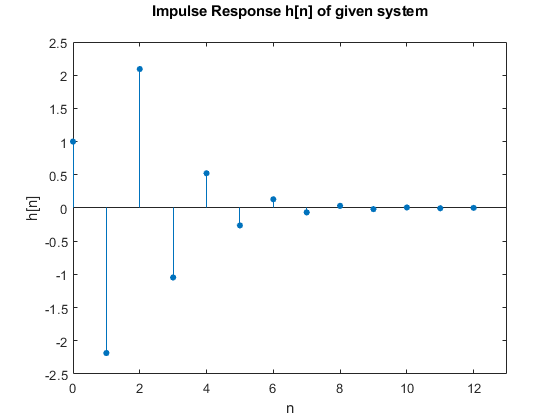


% call get_sys_imp_resp() with above expression Hz to get/plot its impulse resp. h[n]
% <syntax> [h, nh] = get_sys_imp_resp(Hz, P)
[h, nh] = get_sys_imp_resp(Hz, 12);


% >>> task <<< compare this impulse response h[n] with inverse Z-tranform
% expression (h[n]) of H(z) found using iztrans(), for n>=0

% truncate above calculated h[n] to start at n=0
h = h(find(nh==0):end); 
nh = nh(find(nh==0):end);

% call h[n] expression function-handle stored in func_h() to directly compute
% some h[n] values from inverse Z-transform of H(z)
h2 = func_h(nh);

% will return 1 if both h[n] are equal
isequal(round(h, 10), round(h2, 10))

ans = logical
   1


*The next task starts from the next page.*

## Task 3

**Statement:**

Download the provided file $\textrm{almostcaught}\ldotp \textrm{wav}$.

Play the file in MATLAB using sound command and listen to the legend speaking with a tone.

Pass the sampled sound data from the wave file through your system. Plot the DTFT of the sound data before and after passing through the system. 

**Methodology:**

The given system is represented by, 


$$H\left(z\right)\;=\;\frac{1-2\cos \left(\omega_0 \right)z^{-1} +z^{-2} }{1+0\ldotp 5z^{-1} }\;=\;\frac{b_0 +b_1 \;z^{-1} +{b_2 \;z}^{-2} }{a_0 +a_1 \;z^{-1} }$$


Upon comparison, it can be seen that coefficients of the system CCDE are,


$$\begin{array}{l}
b\;=\;\left\lbrace {\;b}_0 \;,\;b_1 \;,\;b_{2\;} \right\rbrace \;=\;\left\lbrace \;1,\;-2\cos \left(\omega_0 \right),\;1\;\right\rbrace \\
a\;=\;\left\lbrace \;a_{0\;} \;,\;a_1 \;\right\rbrace \;=\;\left\lbrace \;1,\;0\ldotp 5\;\right\rbrace 
\end{array}$$


By providing these coefficient arrays to function "$\textrm{get}\_\textrm{system}\_\textrm{out}\left(\right)$" (made in assignment 3) that implements any CCDE, the system output $y\left\lbrack n\right\rbrack$ can be computed for any given input $x\left\lbrack n\right\rbrack$.

In the following case, input $x\left\lbrack n\right\rbrack$ will be the samples of provided .wav file. Here, $\omega_0 =2000\pi /F_s$, and sampling rate $F_s =11025\;\textrm{samples}/\textrm{second}$.

**Code (with results):**

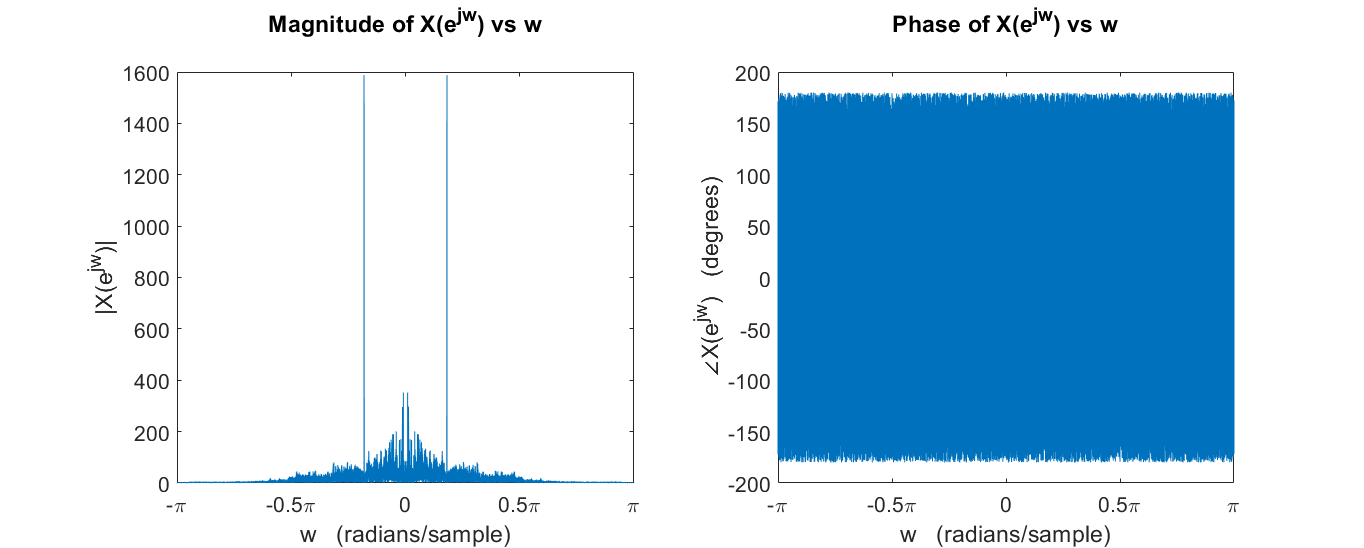

% >>> task <<< read and play the provided almostcaught.wav file
% in MATLAB using the sound command, with Fs = 11025 samples/second

% define sampling frequency Fs and corresponding w0
Fs = 11025;
w0 = 2000*pi/Fs;

% read audio data from almostcaught.wav file
[x, Fs] = audioread('almostcaught.wav');
duration = (length(x)-1)/Fs;

% get and play the audio x(t) using sound command, using above Fs
sound(x, Fs);
% pause execution while the sound is playing
pause(duration);

% >>> task <<< plot DTFT of sound data before passing through system (DTFT of x[n])

% initialize frequency vector for computing DTFT X(w)
w = -pi:2*pi/(length(x)-1):pi;              % for higher/proper DTFT resolution
f = Fs * w/(2*pi);                          % corresponding cont. domain frequencies
x = x.';                                    % convert x[n] to row-vector

% NOTE:
% ------------------
% Since the sound data x[n] is quite large, much higher frequency (w) resolution 
% is needed for DTFT, to properly identify any tones. This requires some 
% consideration in the method by which DTFT is computed, discussed below.
% ------------------
% (1) Matrix-multiplication method,
%               Xw = x * exp(-1i * n' * w);
%     cannot be used since the matrix n'*w will be too large to store in memory.
% ------------------
% (2) For-Loop method,
%               Xw = zeros(1, length(w));
%               for i = 1:length(w)
%                   Xw(i) = x *  exp(-1i * w(i) * n');
%               end
%     cannot be used since it will be quite slow due to many values of w.
% ------------------
% (3) Instead, use the MATLAB in-built function fftshift(x) to first compute 
%     the DFT of x[n] (using FFT algorithm), and then use fftshift(dft) to 
%     transform this DFT to DTFT of x[n], as follows,
%               Xw = fftshift(fft(x));
%     This is the method used below for DTFT computation.
% ------------------

% compute DTFT X(w) using fft() and fftshift()
Xw = fftshift(fft(x));

% obtain magnitude and phase of DTFT X(w)
Xw_mag = abs(Xw);                           % get the magnitude of X(w)
Xw_ang = angle(Xw)*180/pi;                  % get the phase (angle) of X(w) in degrees

% plot magnitude and phase of DTFT X(w)
fig = figure; set(fig,'Units','normalized','Position',[0 0 1.4 1]);

% plot magnitude of X(w) vs w
subplot(1, 2, 1);
plot(w, Xw_mag);
xlabel('w   (radians/sample)'); ylabel('|X(e^{jw})|');
title({'Magnitude of X(e^{jw}) vs w';''}, 'FontSize', 16);
setDTFTradialAxis(1); ax = gca; ax.FontSize = 16;

% plot phase of X(w) vs w
subplot(1, 2, 2);
plot(w, Xw_ang);
xlabel('w   (radians/sample)'); ylabel('∠X(e^{jw})   (degrees)');
title({'Phase of X(e^{jw}) vs w';''}, 'FontSize', 16);
setDTFTradialAxis(1); ax = gca; ax.FontSize = 16;

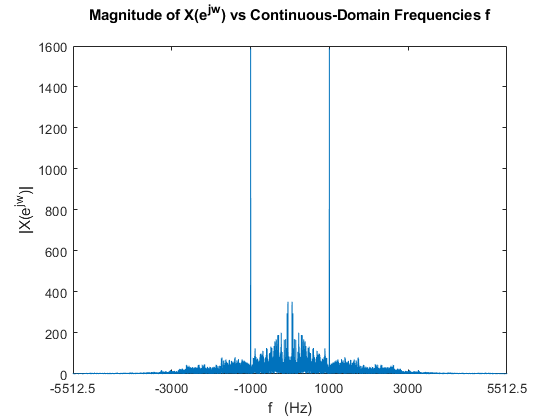


% plot magnitude of X(w) vs continuous-domain frequencies f
fig = figure;
plot(f, Xw_mag);
xlabel('f   (Hz)'); ylabel('|X(e^{jw})|');
xlim([min(f) max(f)]); xticks([min(f) -3000:2000:3000 max(f)]);
title({'Magnitude of X(e^{jw}) vs Continuous-Domain Frequencies f';''});

***Note:***  Sharp tone of high magnitude can be seen in this spectrum $X\left(e^{j\omega } \right)$, at about $F=\pm 1\;\textrm{kHz}$.

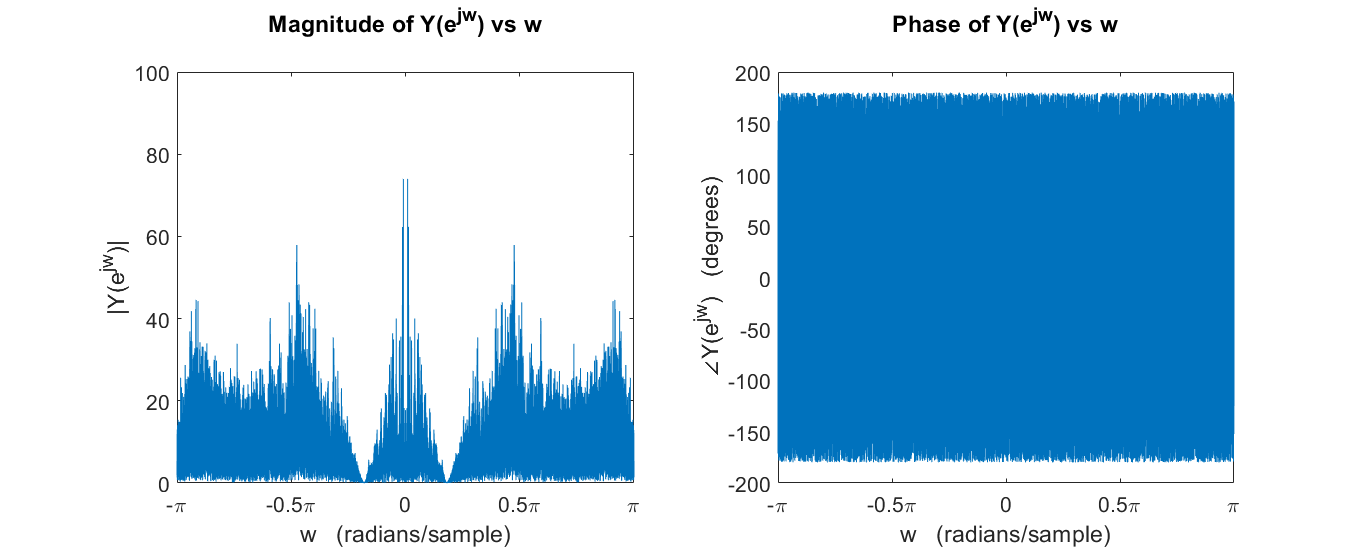

% >>> task <<< pass the sound data through given system, using get_system_out(),
% with the system CCDE coefficients stated in methodology section

% b's and a's in poly. frac H(z)=B(z)/A(z) are (as shown in methodology section),
b = [1 -2*cos(w0) 1];
a = [1 0.5];

% assuming zero initial conditions (rest)
N_aux = zeros(1, length(a)-1);
M_init = zeros(1, length(b)-1);

% compute system output y[n] for 0 <= n < length(x), with input = sound data x[n],
% using get_system_out()
[y, ny] = get_system_out(b, a, x, N_aux, M_init);
duration = (length(y)-1)/Fs;

% get and play the audio y(t) using sound command, using given Fs
sound(y, Fs);
% pause execution while the sound is playing
pause(duration);

% >>> task <<< plot DTFT of sound data after passing through system (DTFT of y[n])

% initialize frequency vector for computing DTFT Y(w)
w = -pi:2*pi/(length(y)-1):pi;              % for higher/proper DTFT resolution
f = Fs * w/(2*pi);                          % corresponding cont. domain frequencies

% compute DTFT Y(w) using fft() and fftshift()
Yw = fftshift(fft(y));

% obtain magnitude and phase of DTFT Y(w)
Yw_mag = abs(Yw);                           % get the magnitude of Y(w)
Yw_ang = angle(Yw)*180/pi;                  % get the phase (angle) of Y(w) in degrees

% plot magnitude and phase of DTFT Y(w)
fig = figure; set(fig,'Units','normalized','Position',[0 0 1.4 1]);

% plot magnitude of Y(w) vs w
subplot(1, 2, 1);
plot(w, Yw_mag);
xlabel('w   (radians/sample)'); ylabel('|Y(e^{jw})|'); 
ylim([0 100]);
title({'Magnitude of Y(e^{jw}) vs w';''}, 'FontSize', 16);
setDTFTradialAxis(1); 
ax = gca; ax.FontSize = 16;

% plot phase of Y(w) vs w
subplot(1, 2, 2);
plot(w, Yw_ang);
xlabel('w   (radians/sample)'); ylabel('∠Y(e^{jw})   (degrees)');
title({'Phase of Y(e^{jw}) vs w';''}, 'FontSize', 16);
setDTFTradialAxis(1); 
ax = gca; ax.FontSize = 16;

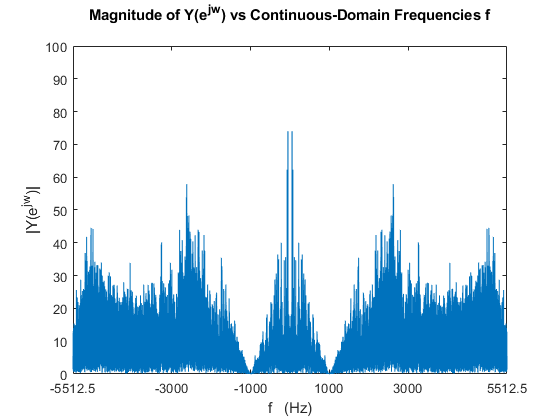


% plot magnitude of Y(w) vs continuous-domain frequencies f
fig = figure;
plot(f, Yw_mag);
xlabel('f   (Hz)'); ylabel('|Y(e^{jw})|');
xlim([min(f) max(f)]); xticks([min(f) -3000:2000:3000 max(f)]); ylim([0 100]);
title({'Magnitude of Y(e^{jw}) vs Continuous-Domain Frequencies f';''});

***Note:***  Compared to the magnitude plot of $X\left(e^{j\omega } \right)$, this magnitude plot of $Y\left(e^{j\omega } \right)$ is zoomed in on the y-axis.

**Question (1):**

Can you identify the tone in the sound spectrum before passing through the system?

**Answer (1):**

Yes, the tone can be visibly identified in sound data $x\left\lbrack n\right\rbrack$'s spectrum magnitude $|X\left(e^{j\omega } \right)|$ (at Page 20, top-left figure). It occurs at about $\omega =\pm \;0\ldotp 5699=\pm \;0\ldotp 1814\pi \;\textrm{radians}/\textrm{second}$. 

For the sampling rate $F_s =11025\;\textrm{samples}/\textrm{second}$, the DT radial frequencies $\omega =\left\lbrack -\pi ,\;\pi \right\rbrack$ correspond to CT frequencies:


$$F\;=\;\left\lbrack -\frac{\Omega_s /2}{2\pi },\;\frac{\Omega_s /2}{2\pi }\right\rbrack \;=\;\left\lbrack -\frac{F_s }{2},\;\frac{F_s }{2}\right\rbrack \;=\;\left\lbrack -5512\ldotp 5,\;5512\ldotp 5\right\rbrack \;\textrm{Hz}$$


The bottom figure on Page 20 shows the spectrum magnitude $|X\left(e^{j\omega } \right)|$ against respective CT frequencies (in $\textrm{Hertz}$). So, the tone identified at $\omega =\pm \;0\ldotp 1814\pi \;\textrm{radians}/\textrm{second}$ corresponds to a tone of CT frequency:


$$\frac{0\ldotp 1814\pi \times 11025}{2\pi }\;\textrm{Hz}\;\approx \;1\;\textrm{kHz}$$


in the audio signal. This tone is also audible in the audio playback signal $x\left(t\right)$ reconstructed from $x\left\lbrack n\right\rbrack$.

**Question (2):**

Can you identify the tone in the sound spectrum after passing through the system?

**Answer (2):**

As discussed in Task 1 Q4 (Page 12-13), the given filter $H\left(z\right)$ has a sharp dip (a cutoff for a single point) around $\omega =\pm \;0\ldotp 1814\pi \;\textrm{radians}/\textrm{second}$ (see Page 12, top-left figure), which for $F_s =11025\;\textrm{samples}/\textrm{second}$ maps to CT frequency $F\approx 1\;\textrm{kHz}$. 

As answered in Q1 above, $1\;\textrm{kHz}$ is also the frequency where the tone lies in the given audio sequence $x\left\lbrack n\right\rbrack$ (see Page 20, bottom figure). 

So, after passing given audio sequence through the system $H\left(z\right)$, the output spectrum is given by,


$$Y\left(e^{j\omega } \right)=H\left(e^{j\omega } \right)X\left(e^{j\omega } \right)$$


which means that resultant magnitude in $Y\left(e^{j\omega } \right)$ at $F=1\;\textrm{kHz}$ is nearly zero (see Page 22, bottom figure). Hence, the tone at $F=1\;\textrm{kHz}$ has been removed in the output sequence $y\left\lbrack n\right\rbrack =h\left\lbrack n\right\rbrack \ast x\left\lbrack n\right\rbrack$, and is no longer present in respective (filtered) audio signal $y\left(t\right)$.

**Question (3):**

Do you hear the tone in the output of your system? Can you relate the output of your system to its (system's) Fourier Transform.

**Answer (3):**

As described in the above answer, the tone identified at $F=1\;\textrm{kHz}$ in sound data $x\left\lbrack n\right\rbrack$ has been removed in output $y\left\lbrack n\right\rbrack$ obtained after passing through given system. Hence, this tone is no longer audible in the output audio signal $y\left(t\right)$ reconstructed from $y\left\lbrack n\right\rbrack$.

The output Fourier Transform is $Y\left(e^{j\omega } \right)=H\left(e^{j\omega } \right)X\left(e^{j\omega } \right)$, magnitude shown in bottom figure at Page 22. Here, $H\left(e^{j\omega } \right)$ is a sinc-filter which has high magnitude around the higher-frequencies (near $\pm \pi$) and lower magnitude at frequencies near $0$, and has a sharp dip (magnitude $\approx 0$) at $F=1\;\textrm{kHz}$. The magnitude of spectrum $X\left(e^{j\omega } \right)$ of input audio sequence can be seen in bottom figure on Page 20; it has a sharp high-magnitude tone at $F=1\;\textrm{kHz}$, and has magnitude becoming smaller towards the higher-frequencies. 

Upon multiplication with $H\left(e^{j\omega } \right)$, the magnitude of frequencies below $1\;\textrm{kHz}$ in $X\left(e^{j\omega } \right)$ is relatively reduced in $Y\left(e^{j\omega } \right)$, the magnitude of frequencies above $1\;\textrm{kHz}$ in $X\left(e^{j\omega } \right)$ is relatively increased in $Y\left(e^{j\omega } \right)$ (with respect to the sinc pattern), and the magnitude at and around frequency $1\;\textrm{kHz}$ is largely reduced. Particularly, at $1\;\textrm{kHz}$, the magnitude is now nearly $0$, thereby eliminating the $1\;\textrm{kHz}$ tone in the given audio signal. This explains the spectrum-magnitude transformation from $X\left(e^{j\omega } \right)$ (input) to $Y\left(e^{j\omega } \right)$ (output), due to the system FT $H\left(e^{j\omega } \right)$.